[audio,fs] = audioread('samples/LUSMEG/raw/XC766593.mp3');

audio = mono(audio);
audio = audio(1:10*fs);

gammaFiltBank = gammatoneFilterBank(NumFilters=64,SampleRate=fs);
audioOut = gammaFiltBank(audio);

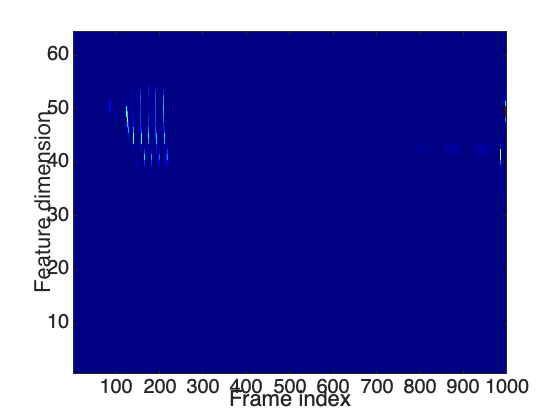

in = audioOut;
winLength = fs*0.02;
winShift = fs*0.01;
[sigLength, numChan] = size(in);

M = floor(sigLength/winShift);
increment = winLength / winShift;

out = zeros(numChan, M);

for m = 1:M
    for i = 1:numChan
        if m < increment
            out(i,m) = in(1:m*winShift,i)'*in(1:m*winShift,i);
        else
            startpoint = floor((m-increment)*winShift);
            to = floor(startpoint+winLength);
            out(i,m) = in(startpoint+1:to,i)'*in(startpoint+1:to,i);
        end
    end
end

imagesc(out);
colormap jet;
ylabel('Feature dimension');
xlabel('Frame index');
set(gca,'YDir','normal');

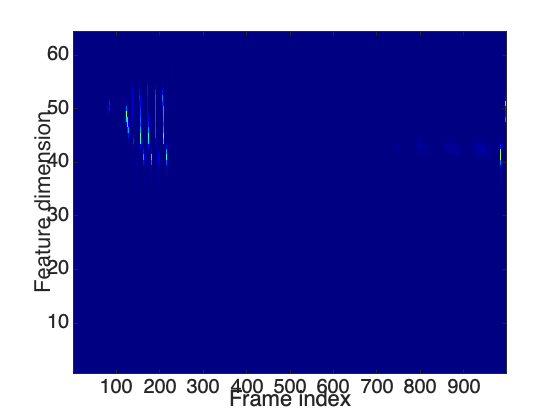

inputSignal = audioOut;
frameLength = 20;
frameShift = 10;
frameSize = floor((frameLength/1000)*fs);
overlapSize = floor((frameShift/1000)*fs);
[numSamples, numChannels] = size(inputSignal);
numFrames = floor((numSamples-frameSize)/overlapSize+1);
frames1 = zeros(numChannels,frameSize,numFrames);

for ii = 1:numChannels
    frames1(ii,:,:) = buffer(inputSignal(:,ii),frameSize,overlapSize,'nodelay');
end

cochleagram1 = squeeze(sum(frames1.^2,2));
imagesc(cochleagram1);
colormap jet;
ylabel('Feature dimension');
xlabel('Frame index');
set(gca,'YDir','normal');

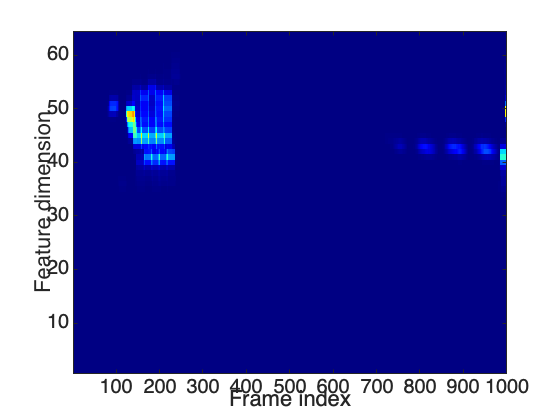

in = audioOut;
winLength = fs*0.2;
winShift = fs*0.01;
[sigLength, numChan] = size(in);

M = floor(sigLength/winShift);
increment = winLength / winShift;

out = zeros(numChan, M);

for m = 1:M
    for i = 1:numChan
        if m < increment
            out(i,m) = in(1:m*winShift,i)'*in(1:m*winShift,i);
        else
            startpoint = floor((m-increment)*winShift);
            to = floor(startpoint+winLength);
            out(i,m) = in(startpoint+1:to,i)'*in(startpoint+1:to,i);
        end
    end
end

imagesc(out);
colormap jet;
ylabel('Feature dimension');
xlabel('Frame index');
set(gca,'YDir','normal');

inputSignal = audioOut;
frameLength = 200;
frameShift = 10;
frameSize = floor((frameLength/1000)*fs);
overlapSize = floor((frameShift/1000)*fs);
[numSamples, numChannels] = size(inputSignal);
numFrames = floor((numSamples-frameSize)/overlapSize+1);
frames2 = zeros(numChannels,960,numFrames);

for ii = 1:numChannels
    frames2(ii,:,:) = buffer(inputSignal(:,ii),frameSize,overlapSize);
end

cochleagram2 = squeeze(sum(frames2.^2,2));
imagesc(cochleagram2);
colormap jet;
ylabel('Feature dimension');
xlabel('Frame index');
set(gca,'YDir','normal');

function out = mrcg(audio,fs)
cochlea1 = log10(cochleagram(audio, fs*0.020, fs*0.010));
cochlea2 = log10(cochleagram(audio, fs*0.200, fs*0.010));
cochlea3 = avg_window(cochlea1, 11);
cochlea4 = avg_window(cochlea1, 23);
out = [cochlea1; cochlea2; cochlea3; cochlea4];
end

function avg = avg_window(data,span)
kernel = ones(span) / span^2;
avg = conv2(data, kernel, 'same');
end

function out = cochleagram(in, winLength, winShift)
[sigLength, numChan] = size(in);

M = floor(sigLength/winShift);
increment = winLength / winShift;

out = zeros(numChan, M);

for m = 1:M
    for i = 1:numChan
        if m < increment
            out(i,m) = in(1:m*winShift,i)'*in(1:m*winShift,i);
        else
            startpoint = floor((m-increment)*winShift);
            to = floor(startpoint+winLength);
            out(i,m) = in(startpoint+1:to,i)'*in(startpoint+1:to,i);
        end
    end
end
end